clearvars
close all
clc

# Full State Feedback Regulator Design of Cart Pole System

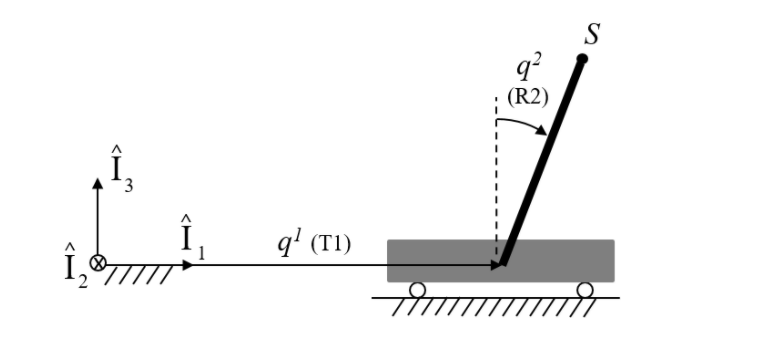

## System Description

The cart translates with respect to the inertial frame in one dimension freely and no external force is applied on the cart. The cart is assumed to be a simple lumped mass block. The pole is a uniformly distributed stick with its centre of mass at its geometric centre. It rotates with respect to the translating cart with the help of a revolute joint. The system is a lumped parameter system which can be represented by ordinary differential equations.

**It is assumed that there is no translational force applied on the cart itself, but a rotational torque is applied at the pole revolute joint with the help of an actuator.**

**The controller output will be this actuator torque which will aim to keep the pole at its inherently unstable equilibrium point.**

## System Parameters:

#### 
$$m_{Cart} = 10 kg$$


#### 
$$m_{Pole} = 5 kg$$


#### 
$$l_{Pole} = 4 m$$


% Cart mass
M = 10;%kg

% Pole mass
m = 5;%kg

% Pole length
L = 4;%meters

% Acceleration due to gravity
g = 9.81; %m/s^2

% Time Step Size
dt = 0.1;

% Time Vector
t_span = [0:dt:10];

## **System Equation of Motion:**

The dynamics of the system can be solved for using the tradiational Euler Lagrange Approoach:

**Kinetic Energy of System:**

### 
$$\frac{1}{2}m_{pole}V_{PoleCOM}^{2} + \frac{1}{2}I_{PoleCOM}\omega_{Pole}^2 + \frac{1}{2}m_{Cart}\dot{x}_{Cart}^2$$


#### Potential Energy of the System:

#### 
$$\frac{m_{Pole}gl_{Pole}}{2}\cos\theta$$


#### Lagrangian of the system:

### 
$$L = $$

$$\frac{1}{2}m_{pole}V_{PoleCOM}^{2} + \frac{1}{2}I_{PoleCOM}\omega_{Pole}^2 + \frac{1}{2}m_{Cart}\dot{x}_{Cart}^2 - \frac{m_{Pole}gl_{Pole}}{2}\cos\theta$$


#### Euler-Lagrange Equation of the system:

### 
$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}}\right) - \frac{\partial L}{\partial q} = Q(t)$$


#### Linearized Equation of Motion (assuming small pole joint rotations):

### 
$$(m_{Cart} + m_{Pole})\ddot{x}_{Cart} + \frac{m_{Pole}l_{Pole}}{2}\ddot{\theta} = 0$$


### 
$$\frac{m_{Pole}l_{Pole}^{2}}{3}\ddot{\theta} + \frac{m_{Pole}l_{Pole}}{2}\ddot{x}_{Cart} - \frac{m_{Pole}gl_{Pole}}{2}\theta = Q(t)$$
 

### State vector of system:

### 
$$\;\mathbf{w}=\;\left\lbrack \begin{array}{c}
x\\
\theta \\
\dot{x} \\
\theta^˙ 
\end{array}\right\rbrack$$


### First Derivative of states:

### 
$$\dot{\mathbf{w}} =\left\lbrack \begin{array}{c}
\dot{x} \\
\theta^˙ \\
\ddot{x} \\
\theta^¨ 
\end{array}\right\rbrack$$


### Initial conditions of the system:

The cart is assumed to be at 0.01 m to the right (positive X axis) initially, with all the other states at zero.

w_0 = [0.01;0;0;0]; 

### State space representation of the system:

The equations of motion of the cart pendulum system can be written as:

### 
$$\dot{\textbf{w}} = \textbf{A}\cdot\textbf{w} + \textbf{B}\cdot\textbf{u}$$


### where,

### $\mathbf{A}=\left\lbrack \begin{array}{cc}
\mathbf{O} & \mathbf{I}\\
{-\mathbf{M}}^{-1} \mathbf{K} & \mathbf{O}
\end{array}\right\rbrack$, system matrix / State Weighing Matrix

### $\mathbf{B}=\left\lbrack \begin{array}{c}
\mathbf{O}\\
{\mathbf{M}}^{-1} 
\end{array}\right\rbrack$, input/excitation matrix

### $\mathbf{u}=\left\lbrack \begin{array}{c}
0\\
Q\left(t\right)
\end{array}\right\rbrack$, input/excitation vector

### $\mathbf{M}=\left\lbrack \begin{array}{cc}
m_{\mathit{Cart}} +m_{\mathit{Pole}}  & \frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2}\\
\frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2} & \frac{m_{\mathit{Pole}} {l_{\mathit{Pole}} }^2 }{3}
\end{array}\right\rbrack$, **mass matrix**

### $\mathbf{K}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -\frac{m_{\mathit{Pole}} gl_{\mathit{Pole}} }{2}
\end{array}\right\rbrack$, **stiffness matrix**

### Required Ouputs of the system:

### 
$$\mathbf{y}\left(t\right)=\left\lbrack \begin{array}{c}
x\left(t\right)\\
\theta \left(t\right)
\end{array}\right\rbrack$$


### 
$$\mathbf{y}\left(t\right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack \mathbf{w}+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \mathbf{u}$$


### 
$$\mathbf{C}=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack \;$$


### 
$$\mathbf{D}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \;$$


% Mass Matrix
M_mat = [m + M,(m*L)/2;
    (m*L)/2,(m*(L)^2)/3];
% Stiffness Matrix
K_mat = [0,0;
    0,(-m*g*L)/2];
% State Weighing matrix
A = [zeros(2,2),eye(2,2);-M_mat\K_mat,zeros(2,2)];
% Controller Cost matrix
% B = [0;0;(-6)/(L*(4*M + m));(12*(M + m))/((m*(L^2))*(4*M + m))];
% B = [0,0;
%     0,0;
%     (4)/(4*M + m) , (-6)/(L*(4*M + m));
%     (-6)/(L*(4*M + m)) , (12*(M + m))/((m*(L^2))*(4*M + m))];

B = [0;0;(4)/(4*M + m);(-6)/(4*M*L + m*L)];

% Output Equation coefficient matrices
C = [1,0,0,0;
    0,1,0,0];
D = zeros(2,1);


### Checking controllability of the system

% Controllability test matrix
P = ctrb(A,B);

if rank(P) == length(A) % comparing rank of controllability test matrix and order of the system
    fprintf('The system is controllable')
else
    fprintf('The system is not controllable')
end

The system is controllable


% Checking the extent of controllability using condition number

condNo = cond(P);
if condNo >20 && condNo < 100
    fprintf('The system is not too strongly controllable')
elseif condNo < 20
    fprintf('The system is strongly controllable')
else
    fprintf('The system is not stongly controllable')
end

The system is strongly controllable

### Required Poles Locations for the Closed Loop System:

V = [-1 - 1i;
    -1 + 1i;
    -5 - 5*1i;
    -5 + 5*1i];

### Computing the required Controller Gains for the desired pole positions:

K = place(A,B,V)

K = 	1.0e+03 *

   -0.3058   -3.1226   -0.3670   -1.3386


### State Space Model of the closed loop system (plant  + controller)

Acl = A - B*K;
Bcl = zeros(size(B));
Ccl = C - D*K;
Dcl = zeros(size(D));
sys_CL = ss(Acl,Bcl,Ccl,Dcl);

### Computing the states and outputs of closed loop system

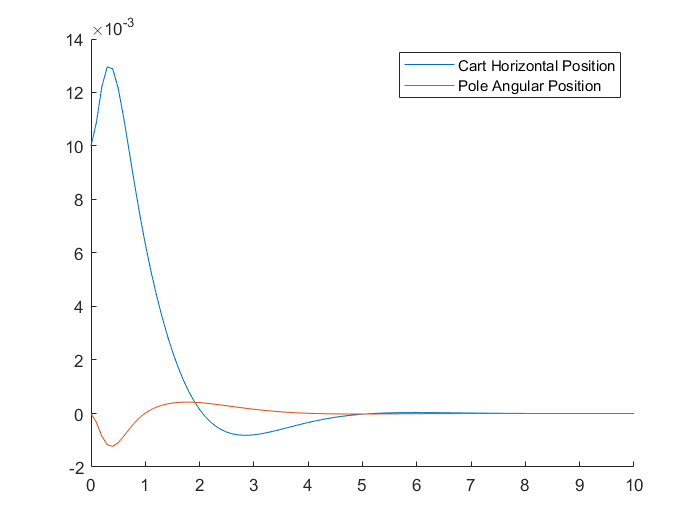

% Using initial function of MATLAB CST Toolbox
[y,t,X] = initial(sys_CL,w_0,t_span);

figure(1)
hold on
plot(t_span,y(:,1))
plot(t_span,y(:,2))
legend('Cart Horizontal Position','Pole Angular Position')

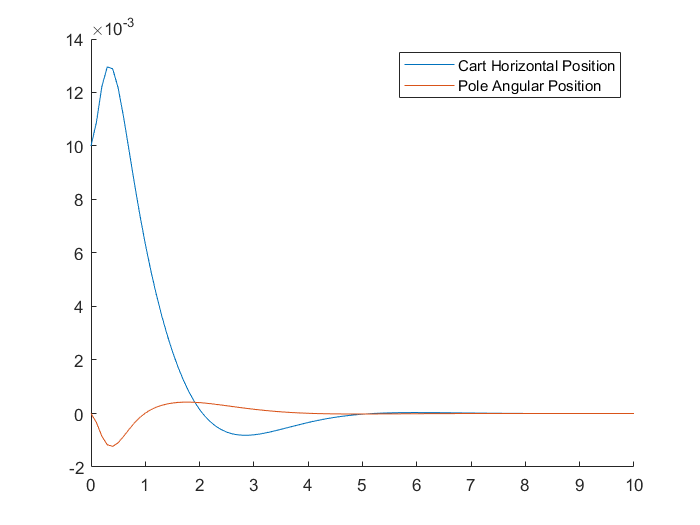


% Using ode45 function
[t,w] = ode45(@(t,w)ClosedLoopStateSpace(t,w,A,B,K),t_span,w_0);

figure(2)
hold on
plot(t,w(:,1))
plot(t,w(:,2))
legend('Cart Horizontal Position','Pole Angular Position')

### Computing the Controller Outputs/Plant inputs required 

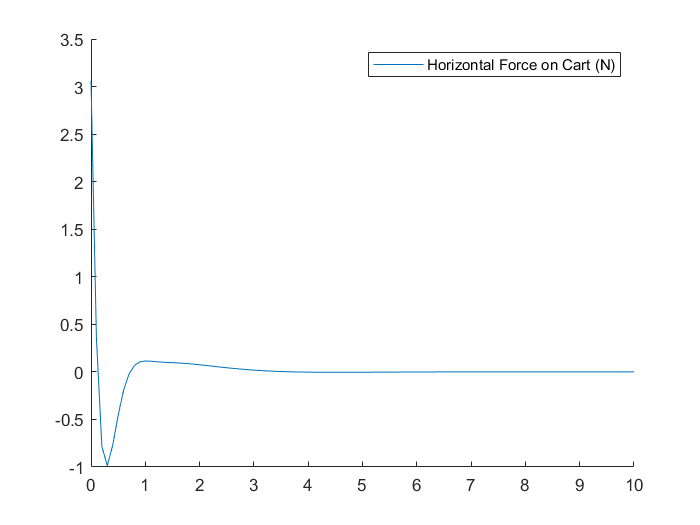

u_controller = -K*w'; % K is rx4, w is 101x4, -K*w' will give is rx101
% r: number of inputs

% Controller Output for prismatic actuator of the cart
u_1 = u_controller(1,:);

% Controller Output for rotational actuator of the pole
% u_2 = u_controller(2,:);

figure(3)
hold on
plot(t_span,u_1)
% plot(t_span,u_2)
legend('Horizontal Force on Cart (N)','Rotational Torque of Pole (N-m)')